# **ACM 11 Homework 2, Part 2/2: Error and stability of heat equation solver**

## **Instructions**

This assignment is **due Friday, April 16, 11:59pm Pacific Time**. You should read the problem set-up in this file and follow the instructions to write and test your code to solve the heat equation. **You should only start this part when you are satisfied that your code in Part 1 is correct! **When you are done with both parts, zip all of your files needed to run the code into a single zip and upload to Canvas -- your final zip should include `ACM11_HW2_part1.mlx, ACM11_HW2_part2.mlx, getMatrix.m, forwardEulerLinear.m, backwardEulerLinear.m, `and` reference.mat.`

## **Problem 4: N = 20, varying timestep size effect on error and stability**

In Part 1 of the homework we fixed $N=100$ and $K=1000$. In this problem, we will try using our solver on a much coarser grid, $N=20$, and look at how the solution accuracy changes as we vary the timestep size, using $\Delta t=\left\{1\text{e-}1,1\text{e-2},1\text{e-}3,1\text{e-}4\right\}$. To measure the effect of the timestep size on the error, we will compare your solutions to a reference solution for the interior points, ${\mathbf{u}}_{\textrm{ref}}$, that we have provided in `reference.mat. `This reference solution is for the 19 interior grid points for this problem, but computed with a timestep of $\Delta \;t_{\textrm{ref}} ={10}^{-5}$. Let $\mathbf{u}_K$ be the solution at the interior grid points at time $T$ calculated from our methods, and define the error as follows:


$$\text{err}=\sqrt{\Delta x}\cdot\|\mathbf{u}^{\text{true}, T}-\mathbf{u}_K\|_2\,,$$


where $\|\cdot\|_2$ is the Euclidean norm.  We will use the same $T=1$ and $\kappa =0\ldotp 02$ and $L=1$ as in Part 1.

**Problem 4a: error and timing plots**

In the block below, set up a computational grid for the N-1 interior points for $N=20$. Call your `getMatrix.m` function from Part 1 to get the matrix **A**, and compute the initial condition from part 1,

$u_{\rm init}(x)=\sin\left(\frac{\pi x}{L}\right) + 2\sin\left(\frac{2\pi x}{L}\right)+0.4\sin\left(\frac{11\pi x}{L}\right)$,

on your computational grid. Then, loop through the following timestep sizes: $\Delta t=\left\{1\text{e-}1,1\text{e-2},1\text{e-}3,1\text{e-}4\right\}$, and compute the solution at the final time $T=1$ using both your forward and backward Euler functions. For each of these solves, time each solve using the `tic/toc` commands and store the times required to solve, and compute the errors as defined above for each method and store these errors. Make the following plots:

(1) Plot all of your forward Euler solutions at the different timestep sizes on a single axis, together with the reference solution, using multiple line styles to make as many of the lines distinguishable as possible. 

(2) Do the same as above for the backward Euler. 

(3) Use a loglog scale to plot the error vs. timestep size for both methods. 

(4) Use a loglog scale to plot the solve time vs. timestep size for both methods.

Include figure titles, axis labels, and legends, and use different line styles when necessary so that as many lines as possible are visible. 

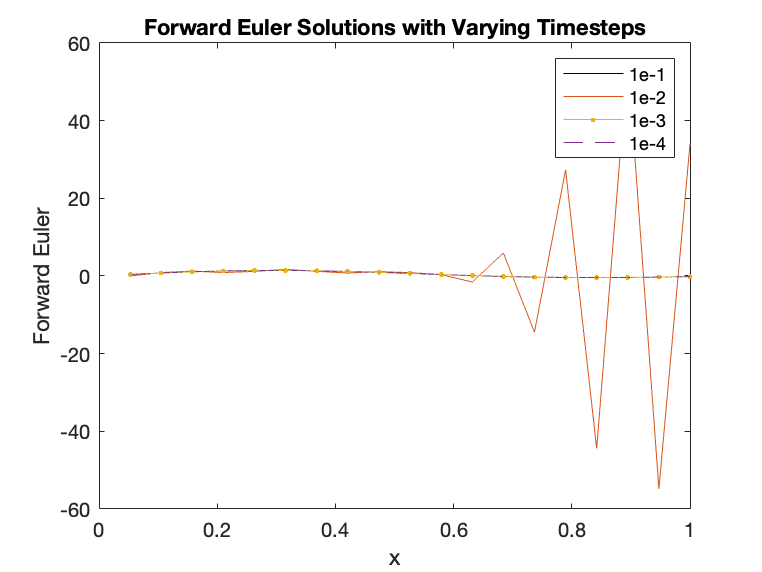

clear; close all

% here is a bunch of set-up for you
kappa = 0.02;
L = 1;
T = 1;
N = 20;
dx = 1/N;
dt_list = [1e-1 1e-2 1e-3 1e-4];

x = linspace(0,1,N);
x = x(2:end)';
A = getMatrix(N,L);

u_init = sin(pi*x/L) + 2*sin(2*pi*x/L) + 0.4*sin(11*pi*x/L);

linestyles = {'-','.-','--',':'};   % you  might find this array of linestyles helpful

% load reference solution and initialize plots
load('reference.mat')

figure(1); clf
plot(x,p4_ref,'k'); hold on

figure(2); clf
plot(x,p4_ref,'k'); hold on

% pre-allocate space to store times/errors
[times,errors] = deal(zeros(length(dt_list),2));

% loop through times in dt_list
for i = 1:length(dt_list)
    dt = dt_list(i);
    
    % call forward Euler, time the solution, and compute the error.
    tic;
    u_final = forwardEulerLinear(u_init,kappa,A,dt,T);
    times(i,1) = toc;
    errors(i,1) = sqrt(dx)*norm(p4_ref - u_final);
    
    figure(1);
    plot(x,u_final,linestyles{i});
    
    % call backward Euler, time the solution, and compute the error.
    % also plot the solution on the figure 2 axes
    tic;
    u_finalb = backwardEulerLinear(u_init,kappa,A,dt,T);
    times(i,2) = toc;
    errors(i,2) = sqrt(dx)*norm(p4_ref - u_finalb);

    figure(2);
    plot(x,u_finalb,linestyles{i});
   
end

figure(1);
% add title, legend, axes labels
title('Forward Euler Solutions with Varying Timesteps');
legend('1e-1','1e-2','1e-3','1e-4');
xlabel('x');
ylabel('Forward Euler');

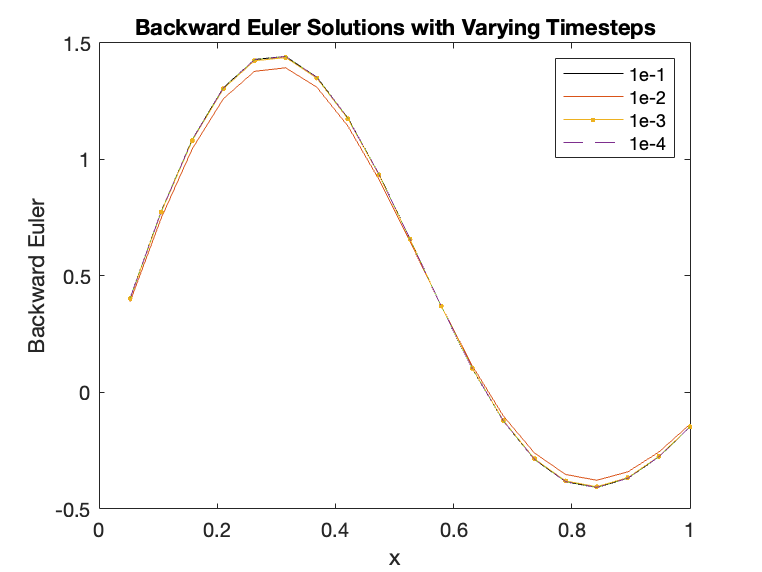


figure(2);
% add title, legend, axes labels
title('Backward Euler Solutions with Varying Timesteps');
legend('1e-1','1e-2','1e-3','1e-4');
xlabel('x');
ylabel('Backward Euler');

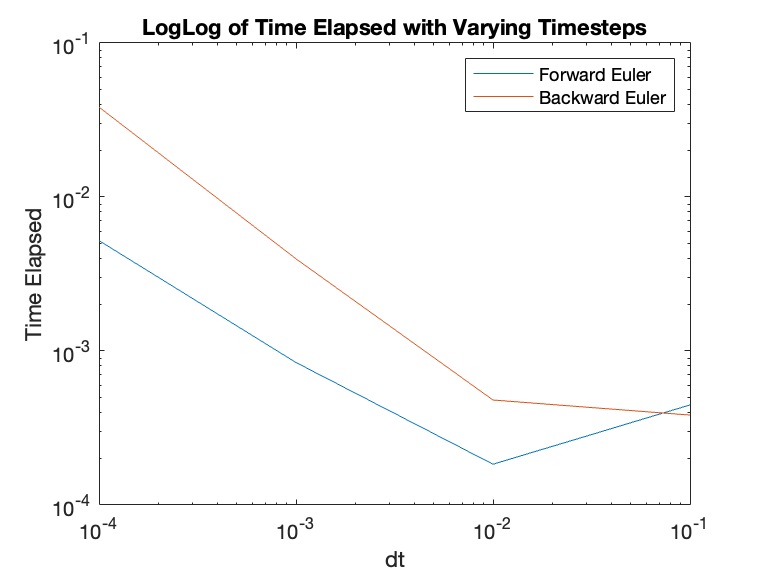


figure(3); clf
% plot loglog of times vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list,times);
title('LogLog of Time Elapsed with Varying Timesteps');
legend('Forward Euler', 'Backward Euler');
xlabel('dt');
ylabel('Time Elapsed');

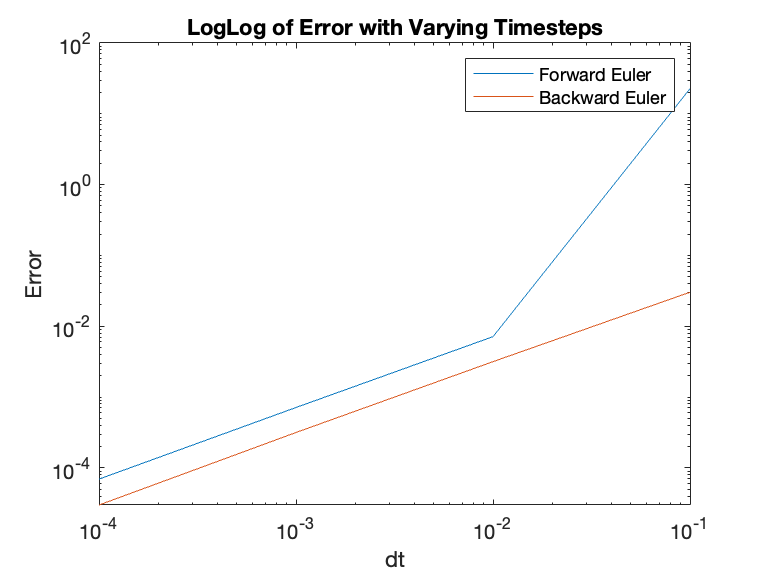


figure(4); clf
% plot loglog of errors vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list,errors);
title('LogLog of Error with Varying Timesteps');
legend('Forward Euler', 'Backward Euler');
xlabel('dt');
ylabel('Error');

**Problem 4b: Discussion**

Timing: which method is faster in general? How do the solve times of each method change as the timestep size is decreased? 

fprintf(['The forwards method is faster in general.\n' ...
    'The solve times of each method increase log-linearly as the timestep is decreased.\n' ...
    'However, we see that for the forwardss method, we see a decrease in time when the timestep is decreased from 1e-2 to 1e-1.'])

The forwards method is faster in general.
The solve times of each method increase log-linearly as the timestep is decreased.
However, we see that for the forwardss method, we see a decrease in time when the timestep is decreased from 1e-2 to 1e-1.

Instability: A solution is unstable if it seems to blow up. This can happen at larger time-step sizes. At what time-steps, if any, do you observe instability for the forward Euler solver? for the backward Euler solver?

fprintf(['We observe instability at the forwards method around timestep 1e-1.\n' ...
    'There is no observed instability for the backwards method.'])

We observe instability at the forwards method around timestep 1e-1.
There is no observed instability for the backwards method.

Error: For the time-step sizes for which the backward Euler and forward Euler methods are stable, how do their errors compare? When the timestep size is shrunk by a factor of 10, how much does the error decrease? What does this say about the order of accuracy of the two ODE solvers?

fprintf(['The error for the forward method is higher by a small constant factor when solutions are stable.\n' ...
    'When the timestep size is shrunk by a factor of 10, the error decreases by a factor of 10.\n' ...
    'This says that the order of accuracy of the ODE solvers is 1.'])

The error for the forward method is higher by a small constant factor when solutions are stable.
When the timestep size is shrunk by a factor of 10, the error decreases by a factor of 10.
This says that the order of accuracy of the ODE solvers is 1.

## **Problem 5: N = 100, varying timestep size effect on error and stability**

Repeat problem 4 here, but this time using an interior grid of N-1 points for N = 100, and answer the discussion questions below. You may want to limit the error plot y-axis to not plot above a $y_{\max } =1$ in order to more clearly see error trends.

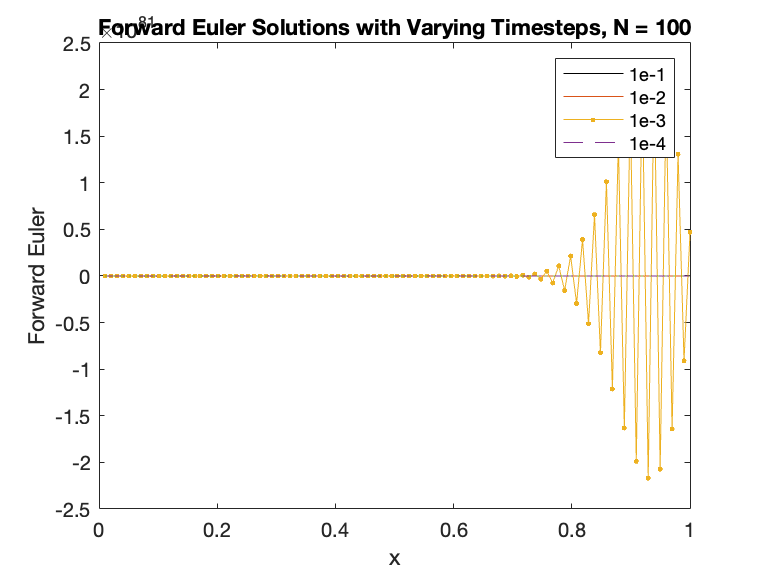


kappa = 0.02;
L = 1;
T = 1;
N = 100;
dx = 1/N;
dt_list = [1e-1 1e-2 1e-3 1e-4];

x = linspace(0,1,N);
x = x(2:end)';
A = getMatrix(N,L);

u_init = sin(pi*x/L) + 2*sin(2*pi*x/L) + 0.4*sin(11*pi*x/L);

linestyles = {'-','.-','--',':'};

% this is loaded from the reference file as well
figure(5); clf
plot(x,p5_ref,'k'); hold on

figure(6); clf
plot(x,p5_ref,'k'); hold on

% pre-allocate space to store times/errors
[times,errors] = deal(zeros(length(dt_list),2));

for i = 1:length(dt_list)
    dt = dt_list(i);
    
    % call forward Euler, time the solution, and compute the error.
    tic;
    u_final = forwardEulerLinear(u_init,kappa,A,dt,T);
    times(i,1) = toc;
    errors(i,1) = sqrt(dx)*norm(p5_ref - u_final);
    
    figure(5);
    plot(x,u_final,linestyles{i});
    
    % call backward Euler, time the solution, and compute the error.
    % also plot the solution on the figure 2 axes
    tic;
    u_finalb = backwardEulerLinear(u_init,kappa,A,dt,T);
    times(i,2) = toc;
    errors(i,2) = sqrt(dx)*norm(p5_ref - u_finalb);

    figure(6);
    plot(x,u_finalb,linestyles{i});
    
end

figure(5);
% add title, legend, axes labels
title('Forward Euler Solutions with Varying Timesteps, N = 100');
legend('1e-1','1e-2','1e-3','1e-4');
xlabel('x');
ylabel('Forward Euler');

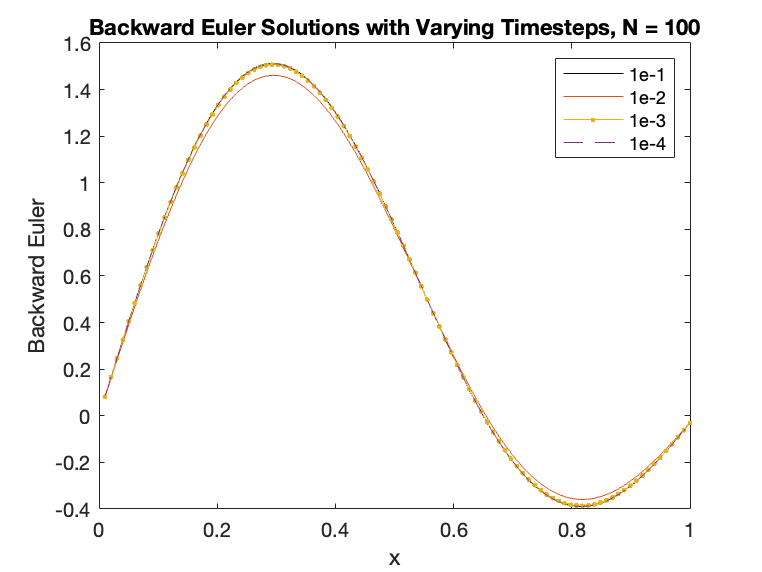


figure(6);
% add title, legend, axes labels
title('Backward Euler Solutions with Varying Timesteps, N = 100');
legend('1e-1','1e-2','1e-3','1e-4');
xlabel('x');
ylabel('Backward Euler');

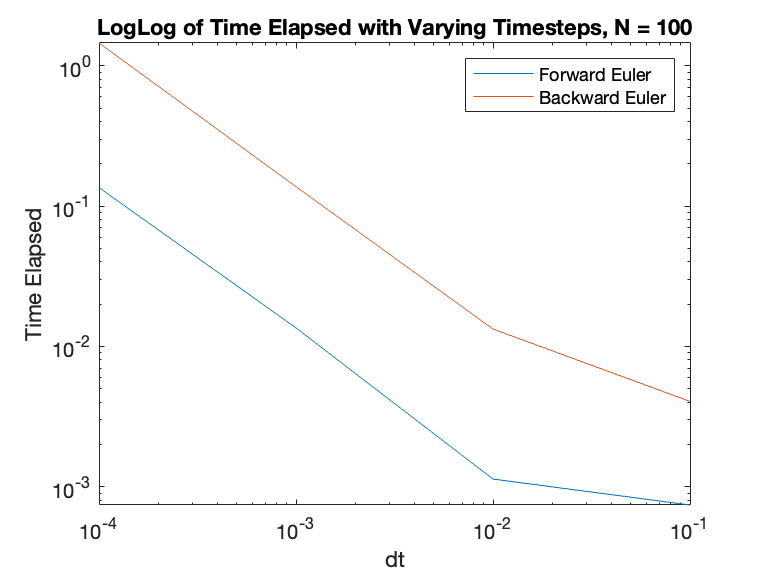


figure(7); clf
% plot loglog of times vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list,times);
title('LogLog of Time Elapsed with Varying Timesteps, N = 100');
legend('Forward Euler', 'Backward Euler');
xlabel('dt');
ylabel('Time Elapsed');

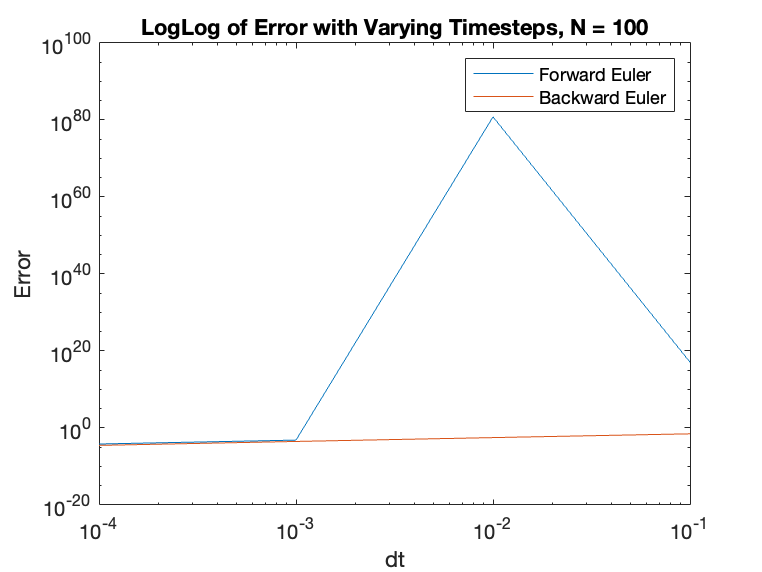



figure(8); clf
% plot loglog of errors vs. dt for both methods, include title, legend, axes
% labels
loglog(dt_list,errors);
title('LogLog of Error with Varying Timesteps, N = 100');
legend('Forward Euler', 'Backward Euler');
xlabel('dt');
ylabel('Error');

**Problem 5b: Discussion**

Timing: How do the solve times of each method change as the timestep size is decreased? How do these solve times compare to the N = 20 case in Problem 4?

fprintf(['The solve times of each method increase semi log-linearly as the timestep size is decreased.\n' ...
    'These solve times are also slower by about a factor of 10 then in the N=20 case.'])

The solve times of each method increase semi log-linearly as the timestep size is decreased.
These solve times are also slower by about a factor of 10 then in the N=20 case.

Instability: At what time-steps, if any, do you observe instability for the forward Euler solver? for the backward Euler solver? How is this different from what you observed in Problem 4? What does this say about how the timestep needs to change for stability as the grid spacing becomes smaller?

fprintf(['Instability is observed at the time step of 1e-2 for the forward method.\n' ...
    'There is no instability observed for the backwards method.\n' ...
    'This is similar to Problem 4, except that the instability is observed at a larger timestep.\n' ...
    'This indicates that the time-step needs to be decreased as grid spacing becomes smaller.'])

Instability is observed at the time step of 1e-2 for the forward method.
There is no instability observed for the backwards method.
This is similar to Problem 4, except that the instability is observed at a larger timestep.
This indicates that the time-step needs to be decreased as grid spacing becomes smaller.

Error: For the time-step sizes for which the backward Euler and forward Euler methods are stable, how do their errors compare? When the timestep size is shrunk by a factor of 10, how much does the error decrease? What does this say about the order of accuracy of the two ODE solvers?

fprintf(['When both methods are stable, we see that the errors are equal.\n' ...
    'When the timestep size is shrunk by a factor of 10, the error decreases by about a factor of 10.\n' ...
    'This says that the order of accuracy of the two ODE solvers is 1.'])

When both methods are stable, we see that the errors are equal.
When the timestep size is shrunk by a factor of 10, the error decreases by about a factor of 10.
This says that the order of accuracy of the two ODE solvers is 1.

**Problem 5c:** **Hours**

How many hours did you spend on this homework, parts 1 and parts 2? Please round to the nearest half hour: 

hours = 4.5

hours = 4.5000